## Exercise 3

### Task 1

clearvars, clc, close all
load('EMG_Practical_3.mat', 'SIG', 'MUPulses', 'fsamp');

EMG = vertcat(SIG{:});

length(EMG(1,:));
binary = zeros(length(MUPulses), length(EMG(1,:)));
for i = 1:length(MUPulses)
    MUPulse = MUPulses{i};
    for j = 1:length(MUPulse)
       index = MUPulse(j);
       binary(i, index) = 1;        
    end
end


windowSize = 0.05;
windowSize_sample = round(fsamp*windowSize);
avg = 0;
spike_tr_avgs = zeros(size(EMG,1), windowSize_sample+1);
all = cell(1,32);

for unit = 1:length(MUPulses)
    resp = binary(unit,:);
    nEvs = sum(resp);
    evIdx = find(resp); 
    for i = 1:size(EMG,1)
        % For each event
        for w = 1:nEvs 
            % Find the indexes of the time window preceding the event
            wIdx = round(evIdx(w) - windowSize_sample/2) : round(evIdx(w) + windowSize_sample/2);
            % Add the stim from this window to the average
            avg = avg + EMG(i,wIdx);
        end
        avg = avg ./ nEvs;
        spike_tr_avgs(i,:) = avg;
    end    
    all{unit} = spike_tr_avgs;
    spike_tr_avgs = zeros(size(EMG,1), windowSize_sample+1);
    avg = 0;
end

convolutions = cell(1,32);

for i = 1:length(MUPulses)    
    for channel = 1:size(EMG,1)
        convolution(channel,:) = conv(binary(i,:), all{i}(channel,:), 'same');
    end
    convolutions{i} = convolution;
end

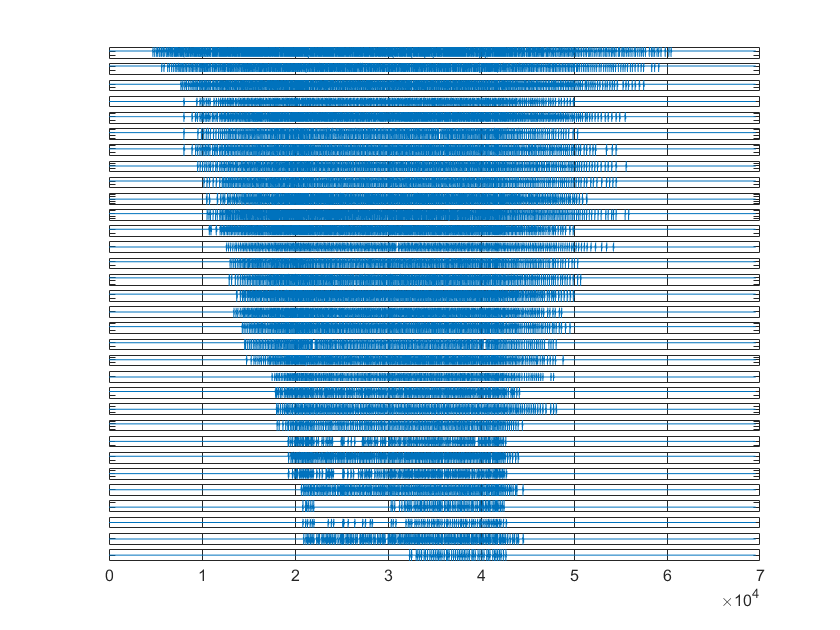

fig_convolutions = figure;
for i = 1:(length(MUPulses)-1)
    subplot(32,1,i);
    plot(convolutions{i}(1,:))
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
end

subplot(32,1,32);
plot(convolutions{32}(1,:))
set(gca,'YTickLabel',[]);


saveas(fig_convolutions, "convolution.jpg")


fig_detailed_convolution = figure;
subplot(2,1,1)
plot(convolutions{1}(1,:))
subplot(2,1,2)
plot(convolutions{1}(1,19000:20800))
fig_detailed_convolution.Position = [100, 100, 700, 450];
saveas(fig_detailed_convolution, 'detailed_convolution.jpg')

### Task 2

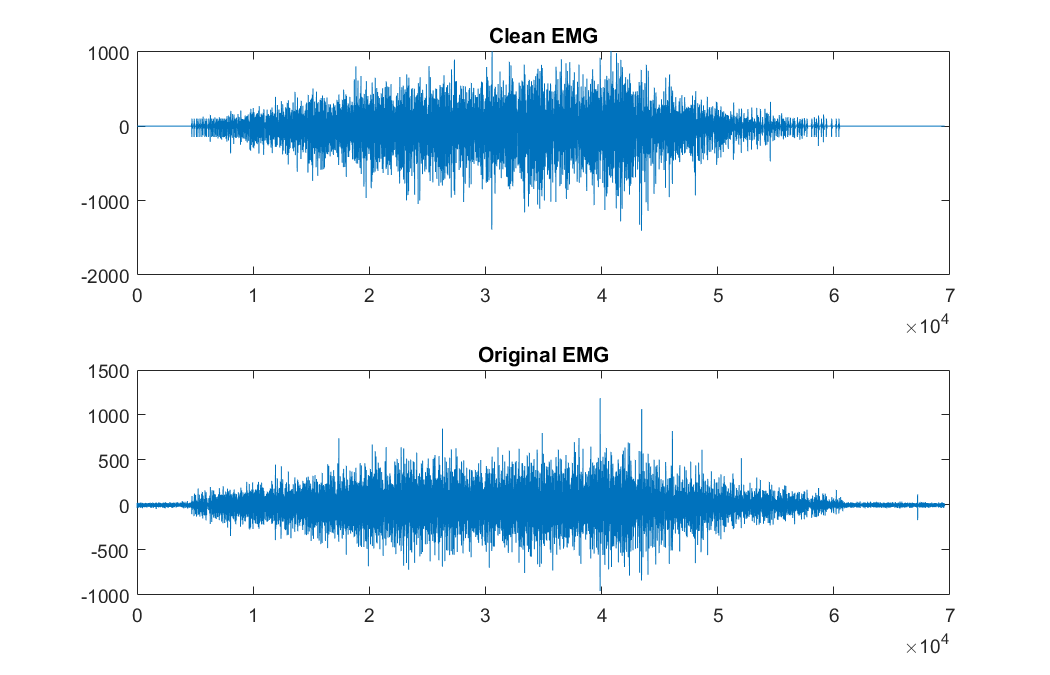

summe = zeros(1,length(EMG(1,:)));
clean_emgs = zeros(size(EMG,1), length(EMG(1,:)));

for channels = 1:size(EMG,1)
    for i = 1:length(MUPulses) 
        summe = summe + convolutions{i}(channels,:);
    end
    clean_emgs(channels,:) = summe;
    summe = zeros(1,length(EMG(1,:)));
end

fig_clen_original_signal = figure;
subplot(2,1,1)
plot(clean_emgs(1,:))
title("Clean EMG")
subplot(2,1,2)
plot(EMG(1,:))
title("Original EMG")
fig_clen_original_signal.Position = [100, 100, 700, 450];

saveas(fig_clen_original_signal, 'cleanVSoriginal.jpg')


### Task 3

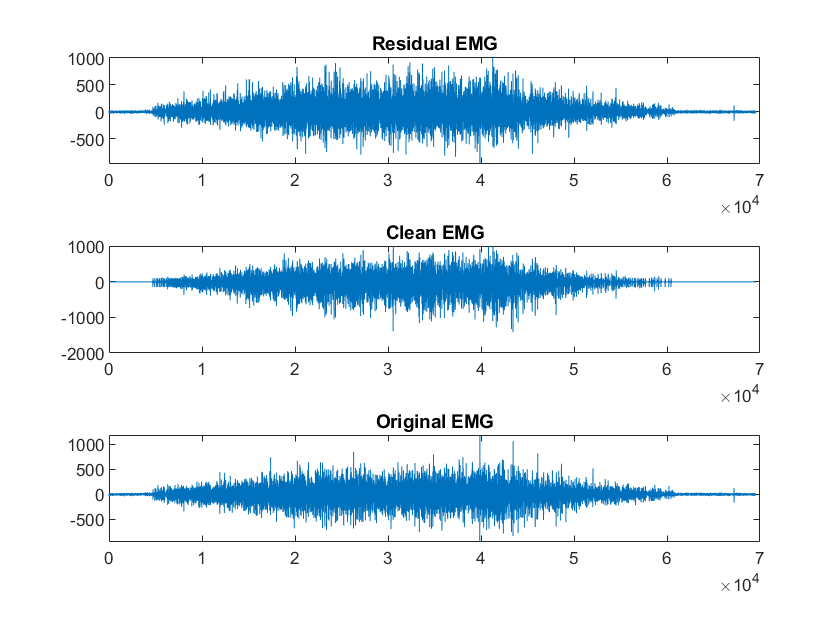

residual_emg = zeros(size(EMG,1), length(EMG(1,:)));

for channels = 1:size(EMG,1)
    residual_emg(channels,:) = EMG(channels,:) - clean_emgs(channels,:);
end

fig_res_clean_orig = figure;
subplot(3,1,1)
plot(residual_emg(1,:));
title("Residual EMG");

subplot(3,1,2)
plot(clean_emgs(1,:))
title("Clean EMG")

subplot(3,1,3)
plot(EMG(1,:))
title("Original EMG")


saveas(fig_res_clean_orig, 'res_clean_orig.jpg')


fig_correlation = figure;
subplot(3,1,1)
correlation1 = xcorr(residual_emg(1,:), EMG(1,:), 'coeff')
plot(correlation1)
title("Correlation between Residual and Original EMG")
subplot(3,1,2)
correlation2 = xcorr(residual_emg(1,:), clean_emgs(1,:), 'coeff')
plot(correlation2)
title("Correlation between Residual and Clean EMG")
subplot(3,1,3)
correlation3 = xcorr(clean_emgs(1,:), EMG(1,:), 'coeff')
plot(correlation3)
title("Correlation between Clean and Original EMG")
saveas(fig_correlation, 'correlation.jpg')


fig_coherence = figure;
subplot(3,1,1)
coh1 = mscohere(residual_emg(1,:), EMG(1,:), hanning(2048))
plot(coh1)
title("Coherence between Residual and Original EMG")
subplot(3,1,2)
coh2 = mscohere(residual_emg(1,:), clean_emgs(1,:), hanning(2048))
plot(coh2)
title("Coherence between Residual and Clean EMG")
subplot(3,1,3)
coh3 = mscohere(clean_emgs(1,:), EMG(1,:), hanning(2048))
plot(coh3)
title("Coherence between Clean and Original EMG")
saveas(fig_coherence, 'coherence.jpg')

